# **Digital Signal Processing**

## **Project**

## Cleaning EEG data using filters.  

#### Project Statement:   

Electroencephalography (EEG) is an essential diagnostic technique that uses tiny electrodes applied to  the scalp to record electrical activity in the brain. Yet, to do an effective analysis, EEG signals must be  free of numerous forms of noise, including line noise. You will learn how to use Digital Signal Processing  (DSP) techniques, with an emphasis on signal filtering and noise reduction.   

#### Objective:   

The aim of this project is to give hands-on experience managing, evaluating, and processing EEG data  using MATLAB. After cleaning EEG data using a variety of DSP techniques, you will examine it in relation  to various brain activity frequency bands.  

#### Tasks:   

1. Installation of MATLAB.  

2. Data Preparation and Preliminary Analysis. 

 a. Detection and removal of line noise.   

3. Filter Design and Implementation. {The cut off frequencies should correspond to delta (0.5 to  4Hz); theta (4 to 7Hz); alpha (8 to 12Hz); sigma (12 to 16Hz) and beta (13 to 30Hz).}  

a. Notch filter.  

b. High pass filter.  

c. Low pass filter.  

d. Band pass filter.  

4. Selection and extraction of 10 selected channels and application of designed filters on the  selected channels.   

5. Submission Report.  

a. A comprehensive report detailing the installation process, the filtering techniques used,  and the outcome of the filtering process.  

b. It should also include the MATLAB code for each filter, and an analysis section with  graphical representations of the EEG signals pre- and post-filtering.  

#### Outcomes:   

1. Ability to design and implement filters tailored to specific requirements.  

2. Enhanced skills in analyzing and interpreting signal data, particularly in the context of signal  integrity and noise removal.

% Load EEG data
load('825_2_PD_REST.mat');

% Sampling rate
fs = 500; 

% Compute PSD using pwelch
channel_to_check = 1; % Channel to check for line noise
[psd, f] = pwelch(EEG.data(channel_to_check, :), [], [], [], fs);

% Find the power at 50 Hz and 60 Hz
[~, idx_50Hz] = min(abs(f - 50));
[~, idx_60Hz] = min(abs(f - 60));
power_50Hz = psd(idx_50Hz);
power_60Hz = psd(idx_60Hz);

% Determine which frequency has higher power
if power_50Hz > power_60Hz
    f0 = 50; % Line noise frequency
else
    f0 = 60; % Line noise frequency
end

% Display the chosen frequency for notch filter
fprintf('Chosen frequency for notch filter: %d Hz\n', f0);

Chosen frequency for notch filter: 60 Hz


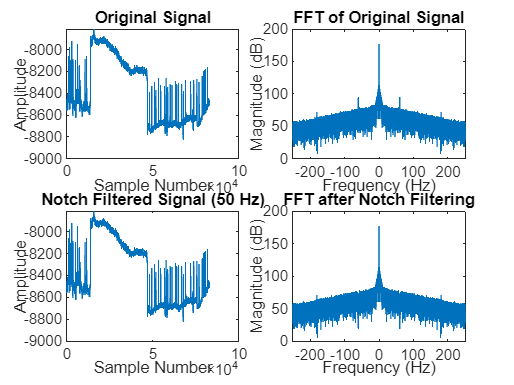


% Define the notch filter to remove the chosen line noise
Q = 30; % Quality factor
[notch_b, notch_a] = iirnotch(f0/(fs/2), f0/(fs/2)/Q);

% Apply the notch filter to each channel
filtered_data_notch = zeros(size(EEG.data));
for i = 1:size(EEG.data, 1)
    filtered_data_notch(i, :) = filtfilt(notch_b, notch_a, EEG.data(i, :));
end

% Plot original vs. notch-filtered signal for one channel
figure;
channel_to_plot = 1;

% Plot original signal
subplot(2, 2, 1);
plot(EEG.data(channel_to_plot, :));
title('Original Signal');
xlabel('Sample Number');
ylabel('Amplitude');

% Compute and plot the FFT of the original signal
subplot(2, 2, 2);
fft_original = fft(EEG.data(channel_to_plot, :));
fft_original_shifted = fftshift(fft_original);
f_fft_original = (-length(fft_original)/2:length(fft_original)/2-1) * (fs / length(fft_original));
plot(f_fft_original, 20*log10(abs(fft_original_shifted)));
title('FFT of Original Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

% Plot notch-filtered signal
subplot(2, 2, 3);
plot(filtered_data_notch(channel_to_plot, :));
title('Notch Filtered Signal (50 Hz)');
xlabel('Sample Number');
ylabel('Amplitude');

% Compute and plot the FFT of the signal after notch filter
subplot(2, 2, 4);
fft_notch_filtered = fft(filtered_data_notch(channel_to_plot, :));
fft_notch_filtered_shifted = fftshift(fft_notch_filtered);
f_fft_notch_filtered = (-length(fft_notch_filtered)/2:length(fft_notch_filtered)/2-1) * (fs / length(fft_notch_filtered));
plot(f_fft_notch_filtered, 20*log10(abs(fft_notch_filtered_shifted)));
title('FFT after Notch Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

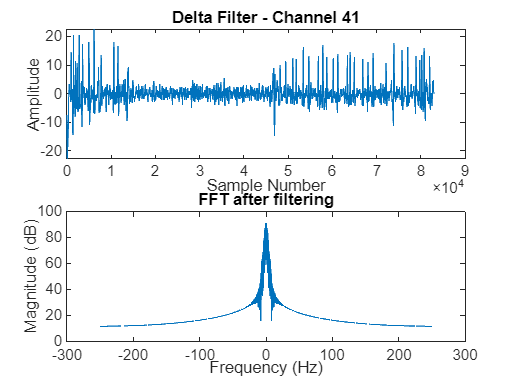

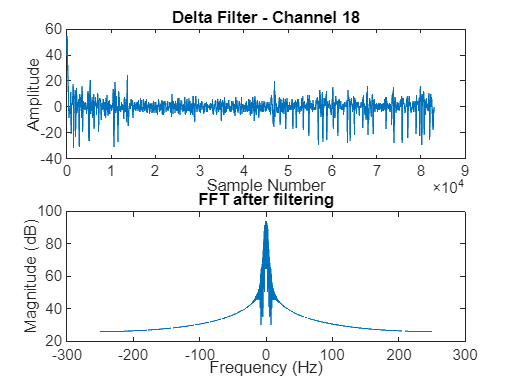

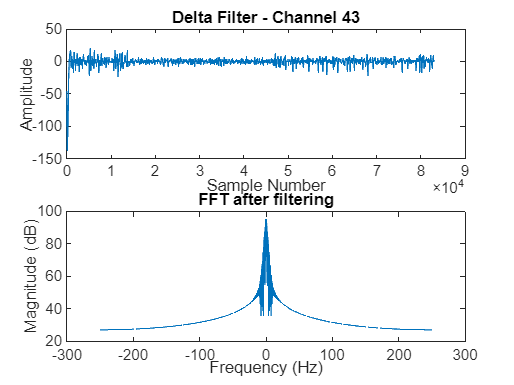

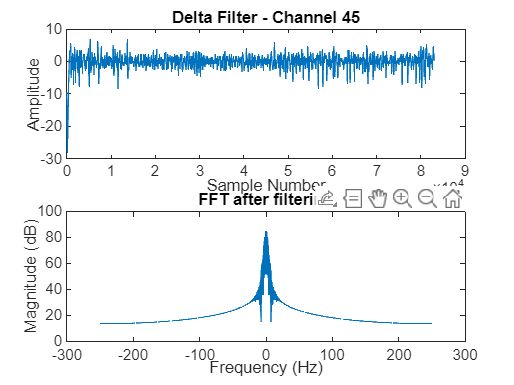

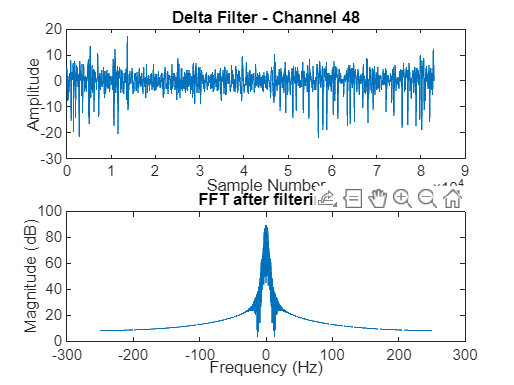

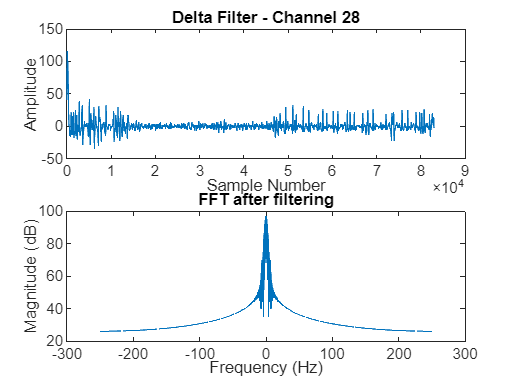

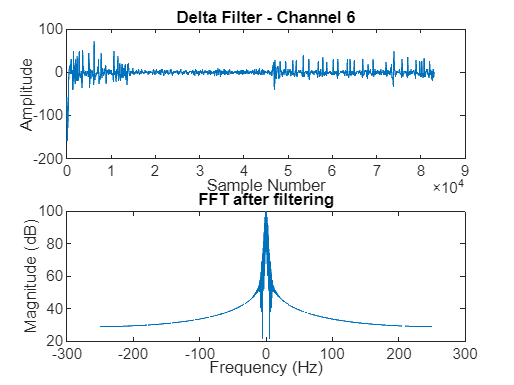

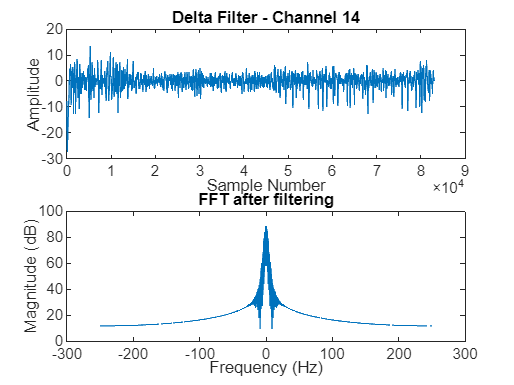


% Store the notch filtered data back into the EEG struct for further processing
EEG.data = filtered_data_notch;

% Filter Design and Implementation
% Define the filter bands
bands = {'delta', 'theta', 'alpha', 'sigma', 'beta'};
band_ranges = [0.5 4; 4 7; 8 12; 12 16; 13 30];

% Initialize the filters struct
filters = struct();
for k = 1:length(bands)
    filters.(bands{k}) = designfilt('bandpassiir', 'FilterOrder', 4, ...
        'HalfPowerFrequency1', band_ranges(k, 1), ...
        'HalfPowerFrequency2', band_ranges(k, 2), ...
        'SampleRate', fs);
end

% Apply filters to the selected channels and plot
% Select 10 random channels
num_channels = size(EEG.data, 1);
random_channels = randperm(num_channels, 10);

filtered_signals = struct();
all_filters = [bands, {'notch'}];

for k = 1:length(all_filters)
    filter_name = all_filters{k};
    filtered_signals.(filter_name) = zeros(length(random_channels), size(EEG.data, 2));
    for i = 1:length(random_channels)
        if strcmp(filter_name, 'notch')
            filtered_signals.(filter_name)(i, :) = filtfilt(notch_b, notch_a, EEG.data(random_channels(i), :));
        else
            filtered_signals.(filter_name)(i, :) = filtfilt(filters.(filter_name), EEG.data(random_channels(i), :));
        end
        
        % Plot FFT of the channel after applying the filter
        figure;
        subplot(2, 1, 1);
        plot(filtered_signals.(filter_name)(i, :));
        title([upper(filter_name(1)) filter_name(2:end) ' Filter - Channel ' num2str(random_channels(i))]);
        xlabel('Sample Number');
        ylabel('Amplitude');

        % Compute and plot the FFT
        subplot(2, 1, 2);
        fft_data = fft(filtered_signals.(filter_name)(i, :));
        fft_data_shifted = fftshift(fft_data);
        f_fft = (-length(fft_data)/2:length(fft_data)/2-1) * (fs / length(fft_data));
        plot(f_fft, 20*log10(abs(fft_data_shifted)));
        title('FFT after filtering');
        xlabel('Frequency (Hz)');
        ylabel('Magnitude (dB)');
    end
end

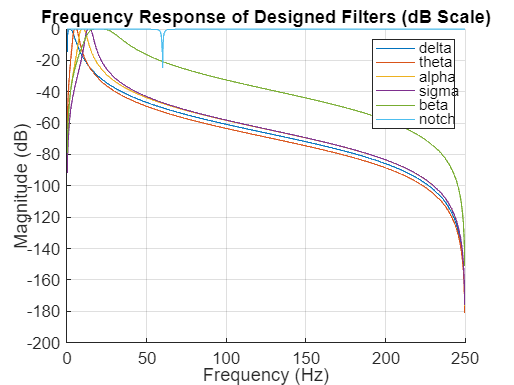


% Plot the combined frequency response of each of the designed filters in dB scale
figure;
hold on;
for k = 1:length(all_filters)
    filter_name = all_filters{k};
    if strcmp(filter_name, 'notch')
        [h, f] = freqz(notch_b, notch_a, 1024, fs);
    else
        [h, f] = freqz(filters.(filter_name), 1024, fs);
    end
    plot(f, 20*log10(abs(h)), 'DisplayName', filter_name);
end
legend;
title('Frequency Response of Designed Filters (dB Scale)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
hold off;

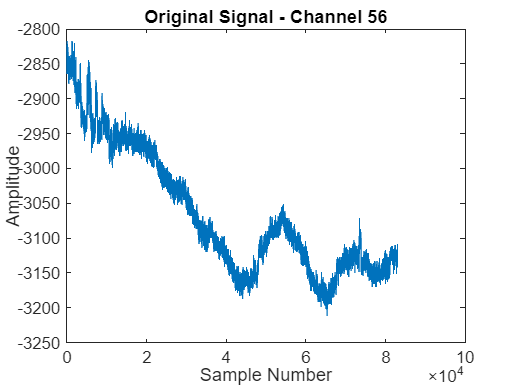


% Sequential filtering on one random channel
random_channel = randi([1 num_channels], 1);
sequential_filtered_signal = EEG.data(random_channel, :);

figure;
plot(sequential_filtered_signal);
title(['Original Signal - Channel ' num2str(random_channel)]);
xlabel('Sample Number');
ylabel('Amplitude');

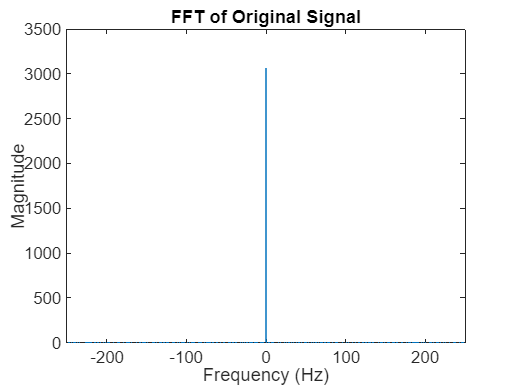


% Plot FFT of original signal
N = length(sequential_filtered_signal);
frequencies = (-N/2:N/2-1)*(fs/N); % Frequency range
original_signal_fft = fftshift(fft(sequential_filtered_signal));

figure;
plot(frequencies, abs(original_signal_fft)/N);
title('FFT of Original Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([-fs/2 fs/2]);

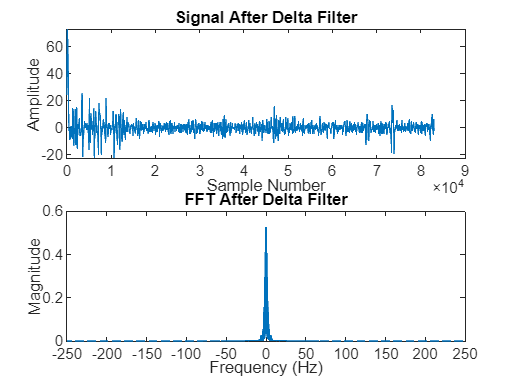

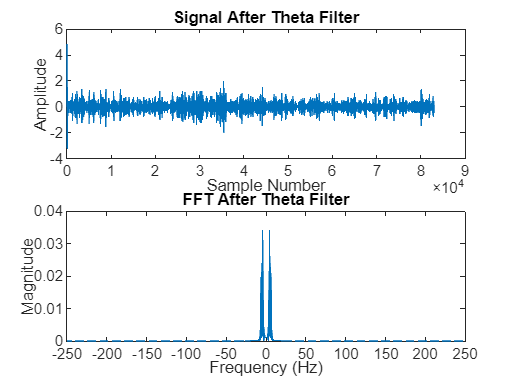

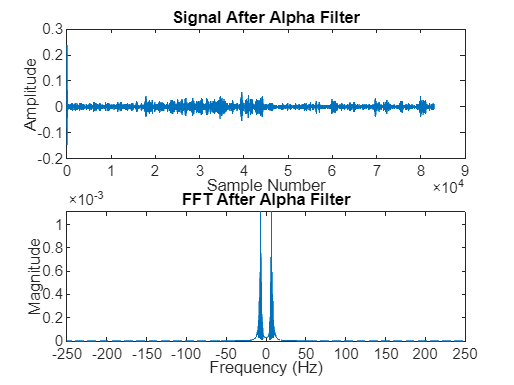

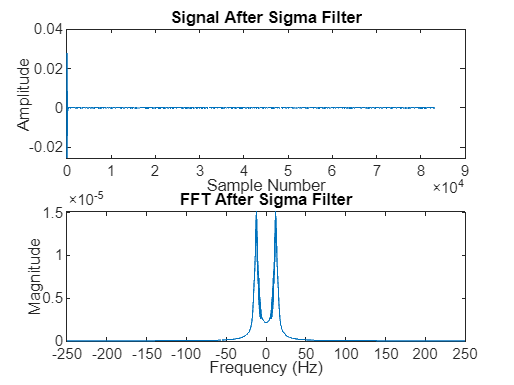

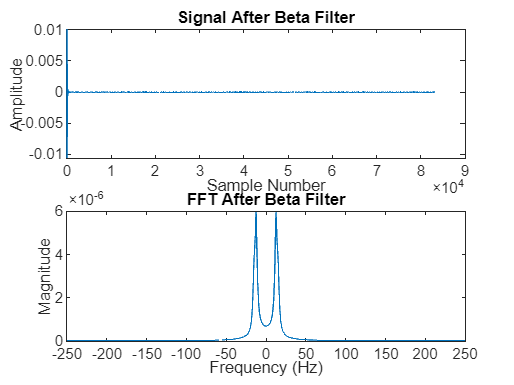

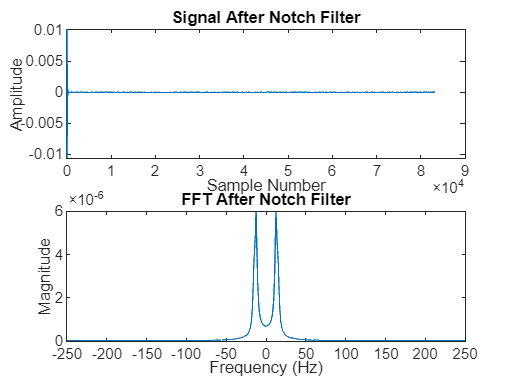


% Apply all filters sequentially on the random channel and plot FFT after each filter
for k = 1:length(all_filters)
    filter_name = all_filters{k};
    if strcmp(filter_name, 'notch')
        sequential_filtered_signal = filtfilt(notch_b, notch_a, sequential_filtered_signal);
    else
        sequential_filtered_signal = filtfilt(filters.(filter_name), sequential_filtered_signal);
    end

    % Plot the signal after passing through each filter
    figure;
    subplot(2, 1, 1);
    plot(sequential_filtered_signal);
    title(['Signal After ' upper(filter_name(1)) filter_name(2:end) ' Filter']);
    xlabel('Sample Number');
    ylabel('Amplitude');

    % Compute and plot FFT after each filter
    filtered_signal_fft = fftshift(fft(sequential_filtered_signal));
    subplot(2, 1, 2);
    plot(frequencies, abs(filtered_signal_fft)/N);
    title(['FFT After ' upper(filter_name(1)) filter_name(2:end) ' Filter']);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    xlim([-fs/2 fs/2]);
end